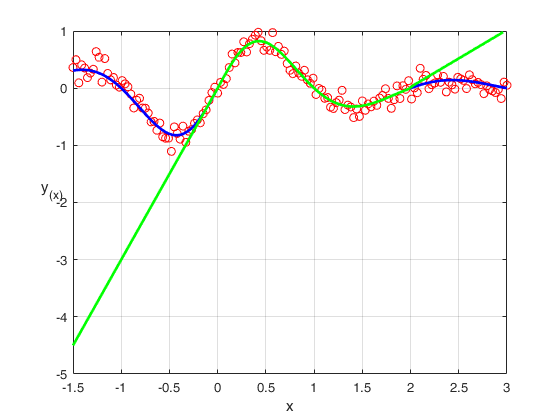

x = -1.5:0.03:3;
func = @(x) sin(pi.*x)./((x.^2)+1);
y = func(x);
t = awgn(func(x),20);  

plot(x,t,"ro");
hold on;
plot(x,y,"b","LineWidth",2);
grid on;

xlabel("x");
y_label = ylabel("y_{(x)}","Rotation",0);

x1 = -1.5:0.03:0-0.03;
x2 = 0:0.03:2;
x3 = 2+0.03:0.03:3-0.03;

y1 = 3.*x1; 
y2 = func(x2); 
y3 = x3-x2(end); 


x = [x1, x2, x3];
y = [y1, y2, y3];

plot(x,y,"g","LineWidth",2);